% AAE364L Lab1 Data Analysis MATLAB Script
% Tomoki Koike
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Load the data
load('matlab_koike.mat');
t = y.time;
pos = y.signals.values;

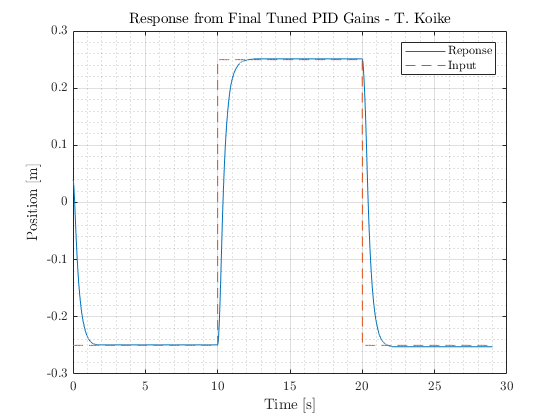

% Plot the results 

% The square wave 
T = 20;  % period
A = 0.25;  % amplitude
sqr = A * square(2*pi/20 * (t - 10));

fig1 = figure;
plot(t, pos)
title('Response from Final Tuned PID Gains - T. Koike')
xlabel('Time [s]')
ylabel('Position [m]')
grid on; grid minor; box on;
hold on;
plot(t, sqr, '--')
hold off
legend('Reponse', 'Input')
saveas(fig1, 'tuned_PID_response.png');

% Estimate the transfer function the system to find the rise time, percent overshoot, 
% settling time, and steady state error

data = iddata(pos, sqr, 0.001);
sys = tfest(data, 4);
S =stepinfo(sys);